## Identificacion del sistema lazo cerrado

load('E:\Mercury\Control ROBOT\Identificacion_Control\caracterizacion.mat');
carpeta='E:\Mercury\control ROBOT\Escalones\';
archivos=dir(strcat(carpeta,'*.txt'));
datos=separarEscalones(archivos,carpeta);
prueba=6;
motor=4;
plot(datos{prueba,1}.datos(:,1),datos{prueba,1}.datos(:,2))
hold on
plot(datos{prueba,1}.datos(:,1),datos{prueba,1}.datos(:,motor+2));
polos=pole(tf1)';
sys=zpk([],[polos -130 ],0.68*130*34.82);
lsim(sys,datos{prueba,1}.datos(:,2),datos{prueba,1}.datos(:,1));

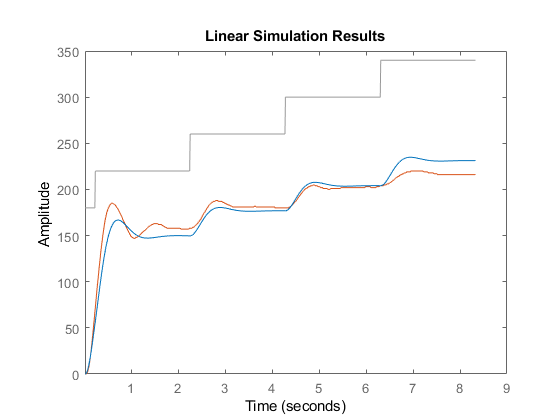

hold off

## Identificacion sistema lazo abierto

K=50;
syms s ;
s=tf('s');
frecuencia=2;
Wc=2*pi*frecuencia;
Vmotor=(95*6)*0.042/( (s^2 + 33*s + 95)* (s+6))


Vmotor =
 
            23.94
  --------------------------
  s^3 + 39 s^2 + 293 s + 570
 
Continuous-time transfer function.



sys


sys =
 
              3078.1
  ------------------------------
  (s+130) (s^2 + 6.342s + 34.82)
 
Continuous-time zero/pole/gain model.



Se verifica que el modelo sea el correcto realizando la realimentacion con la ganacia usada para obtener los datos

feedback(K*Vmotor,1)


ans =
 
             1197
  ---------------------------
  s^3 + 39 s^2 + 293 s + 1767
 
Continuous-time transfer function.



Grafico de la respuesta ante escalon del sistema encontrado

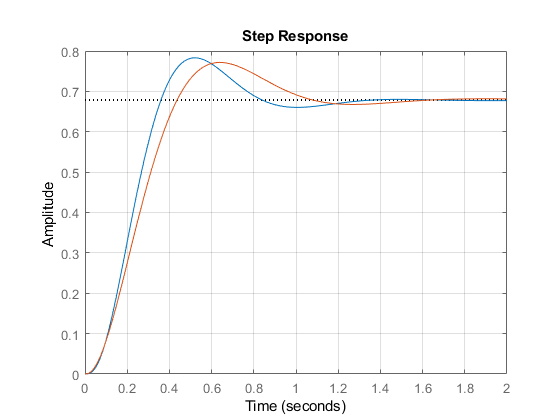


step(feedback(K*Vmotor,1));
hold on
step(sys)
hold off
grid on

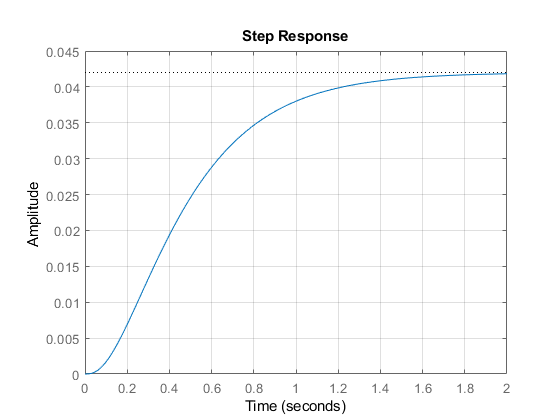

figure()
step(Vmotor);
grid on

## Control PID

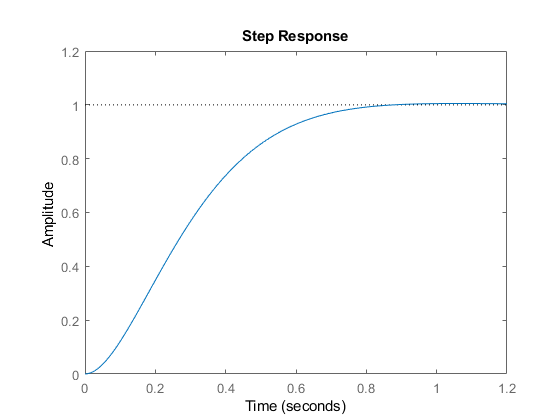

T=0.09;
ov=0.005;
z=sqrt(log(ov)^2/(log(ov)^2+pi^2));
ts=0.8;
wn=4/(z*ts);
pd=-z*wn+wn*sqrt(1-z^2)*i;
pd1=-z*wn-wn*sqrt(1-z^2)*i;
probe=zpk([],[pd pd1],wn^2);
step(probe);

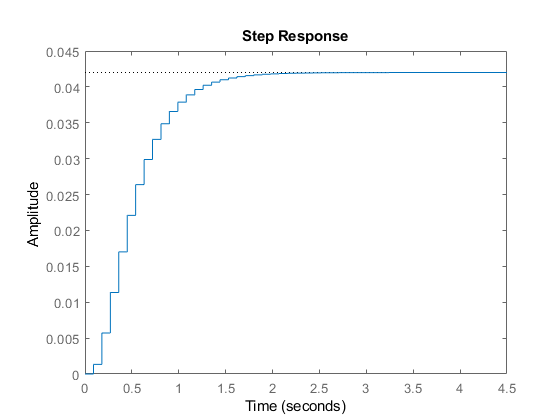

pd_dis=exp(pd*T); % polos discretos
sysd=c2d(Vmotor,T); % sistema discreto
step(sysd);

%% PID
syms z;
z=tf('z');
ap=angle(evalfr(1/(z^2-z),pd_dis))*180/pi;
ac=180-angle(evalfr(sysd,pd_dis))*180/pi;
az = ac - ap

az = 199.5405

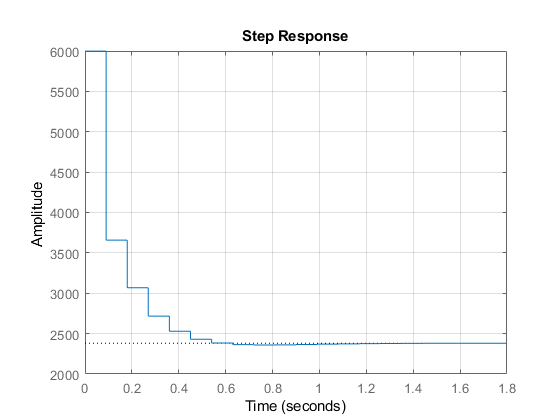

if az>360
    az=az-360;
end
az2=131;
az1=az-az2;
if(az2>90)
    if real(pd_dis)>0
        a1=real(pd_dis)+imag(pd_dis)/tand(180-az2);
    else
        a1=-(abs(real(pd_dis))-imag(pd_dis)/tand(180-az2));
    end
else
     if real(pd_dis)>0
        a1=real(pd_dis)-imag(pd_dis)/tand(az2);
     else
        a1=-(imag(pd_dis)/tand(az2)+abs(real(pd_dis)));
    end
    
end
if(az1>90)
    if real(pd_dis)>0
        a=real(pd_dis)+imag(pd_dis)/tand(180-az1);
    else
        a=-(abs(real(pd_dis))-imag(pd_dis)/tand(180-az1));
    end
else
     if real(pd_dis)>0
        a=real(pd_dis)-imag(pd_dis)/tand(az1);
     else
        a=-(imag(pd_dis)/tand(az1)+abs(real(pd_dis)));
    end
    
end
c=(z-a1)*(z-a)/(z^2-z);
k1= 1/abs(evalfr(sysd*c,pd_dis));
c=k1*c;
sysd_controlado=feedback(c*sysd,1);
sysd_controlado=feedback(c,sysd);
step(100*sysd_controlado);
grid on

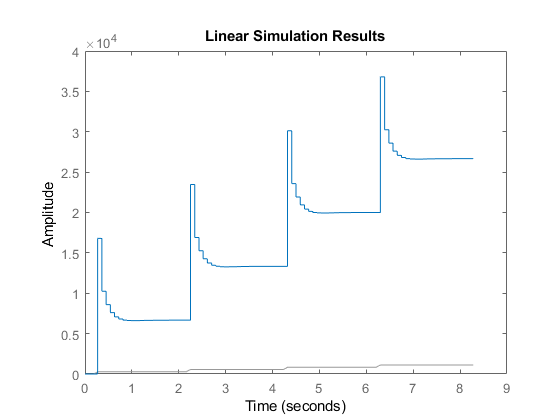

lsim(sysd_controlado,2.5*2.8*(datos{prueba,1}.datos(1:9:end,2)-180),datos{prueba,1}.datos(1:9:end,1));

function y=separarEscalones(archivos,carpeta)
    for i=1:length(archivos)
        datos=csvread(strcat(carpeta,archivos(i).name),2);
        title=archivos(i).name;
        info_title=strsplit(title(1:length(title)-4),'_');
        a=struct;
        a.datos=datos;
        a.title=title;
        a.direccion=cellstr(info_title(4));
        a.voltaje=cell2mat(info_title(5));
        a.superficie=cellstr(info_title(3));
        c(i,1)={a};  
    end
    y=c;
end